# Platooning Figures

This script specifically made to plot class weight histograms for Denges and Monte Ceneri 2017 for the platooning paper.

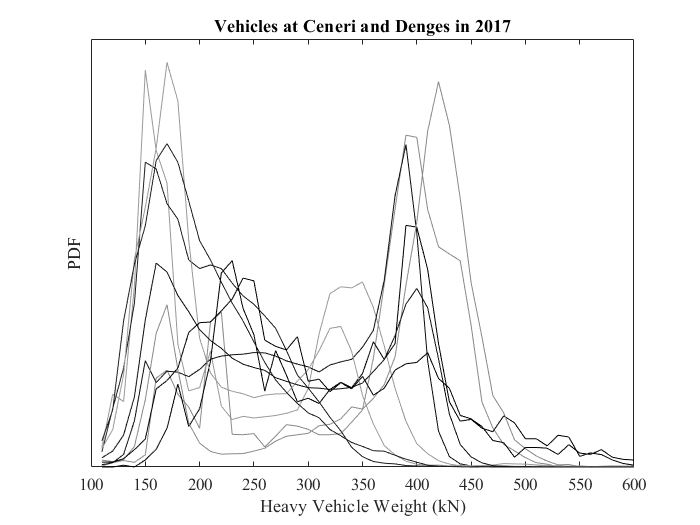

clear
clc
close all
format long g

% INPUT -----------
Year = 2017;
SName = {'Ceneri'; 'Denges'};

% Initialize Figure
figure
% Add title
title(sprintf('Vehicles at %s and %s in %i',SName{1},SName{2},Year),'FontName','times')
xlabel('Heavy Vehicle Weight (kN)','FontName','times')
ylabel('PDF','FontName','times')
box on
hold on
set(gca,'ytick',[],'yticklabel',[],'FontName','times')

% Set x values to be use globally
x_values = 0:1:1000;

% X Stuff
Step = 10;
LimitL = 100;
LimitR = 600;
X = LimitL:Step:LimitR;
x = X(1:end-1) + diff(X);

FaceAlpha = 0.7;

for i = 1:length(SName);
    
    % Load file
    load(['PrunedS1 WIM/',SName{i},'/',SName{i},'_',num2str(Year),'.mat']);
    
    % Let the Classify function add the .CLASS column to PD
    [PDC] = Classify(PD);
    
    % Must redo last two prunings because PDC draws fresh PD w/ only Stage 1
    % 1. Disqualification by weight (try under 6 or 10 tonnes)
    PDC = PDC(PDC.GW_TOT > 6000,:);
    % 2. Disqualification by Swiss10 Class (exclude 2,3,4,6)
    % Not all years have proper Sw10 data... therefore exclude, not include
    PDC(PDC.CS == 2 | PDC.CS == 3 | PDC.CS == 4 | PDC.CS == 6,:) = [];
    % Get rid of overweight classes and class 11bis
    PDC.CLASS(PDC.CLASS > 39 & PDC.CLASS < 50) = 0;
    PDC.CLASS(PDC.CLASS == 119) = 0;
    
    % TrTyps
    TrTyps = [11; 12; 22; 23; 111; 11117; 1127; 12117; 122; 11127; 1128; 1138; 1238];

    for j = [3, 4, 11, 12, 13]
        
        
        color{j} = ((13-j)/(13))*(200/255)*[1, 1, 1];
        
        y = histcounts(PDC.GW_TOT(PDC.CLASS == TrTyps(j))*0.00980665,'BinEdges',X,'normalization','pdf');
        plot(x,y,'color' ,color{j},'DisplayName',num2str(TrTyps))
        
        
        
    end
end

% Let the Classify function add the .CLASS column to PD
load(['PrunedS1 WIM/',SName{1},'/',SName{1},'_',num2str(Year),'.mat']);
PDC = Classify(PD);
load(['PrunedS1 WIM/',SName{2},'/',SName{2},'_',num2str(Year),'.mat']);
PDC = [PDC; Classify(PD)];

% Try certain methods of predisqualification to see if we get better
% coverage

% Must redo last two prunings because PDC draws fresh PD w/ only Stage 1
% 1. Disqualification by weight (try under 6 or 10 tonnes)
PDC = PDC(PDC.GW_TOT > 6000,:);
% 2. Disqualification by Swiss10 Class (exclude 2,3,4,6)
% Not all years have proper Sw10 data... therefore exclude, not include
PDC(PDC.CS == 2 | PDC.CS == 3 | PDC.CS == 4 | PDC.CS == 6,:) = [];
%PDC = PDC(PDC.CS == 1 | PDC.CS == 5 | PDC.CS == 8 | PDC.CS == 9 | PDC.CS == 10,:);
% Get rid of overweight classes and class 11bis
PDC.CLASS(PDC.CLASS > 39 & PDC.CLASS < 50) = 0;
PDC.CLASS(PDC.CLASS == 119) = 0;

vector = [11 12 22 23 111 11117 1127 12117 122 11127 1128 1138 1238];% 0];
w = zeros(length(vector),1); x = w;

for i = 1:length(vector)
    w(i) = sum(PDC.GW_TOT(PDC.CLASS == vector(i)));
    w1(i) = prctile(PDC.GW_TOT(PDC.CLASS == vector(i)),5);
    w2(i) = mean(PDC.GW_TOT(PDC.CLASS == vector(i)));
    w3(i) = prctile(PDC.GW_TOT(PDC.CLASS == vector(i)),95);
    x(i) = sum(PDC.CLASS == vector(i));
    len(i) = mean(PDC.LENTH(PDC.CLASS == vector(i)));
end

% Get total weight of trucks, TW
TW = sum(w);
% Get number of trucks, NT
NT = height(PDC);

MWx = [vector' w./x*0.00980665 100*w/TW w./x*0.00980665./(len'/100)]

MWx =                         11          122.314674499317          13.2106514985843          12.0619126736069
                        12          186.563667164001          6.74781648496319          15.8945330114567
                        22          227.323653087854          6.14557247102296          24.7894997715535
                        23           356.36986363966          2.45400990463732          35.7837423143325
                       111          165.526070940455          1.30911593619669          11.1408788803054
                     11117           201.18717689477          4.41452724745103          10.5504294073893
                      1127          248.627294954207          2.84251423323319          12.8767542869511
                     12117          289.026813853098          4.18463630943767          15.3312865416853
                       122          282.682793894595          2.89969640039766          15.1836005785901
                     11127          255.955957426

format bank
array2table(MWx)

ans = 13×4 table
      MWx1       MWx2     MWx3     MWx4 
    ________    ______    _____    _____

       11.00    122.31    13.21    12.06
       12.00    186.56     6.75    15.89
       22.00    227.32     6.15    24.79
       23.00    356.37     2.45    35.78
      111.00    165.53     1.31    11.14
    11117.00    201.19     4.41    10.55
     1127.00    248.63     2.84    12.88
    12117.00    289.03     4.18    15.33
      122.00    282.68     2.90    15.18
    11127.00    255.96     0.25    14.01
     1128.00    200.67    11.32    12.41
     1138.00    289.11    43.71    17.80
     1238.00    308.93     0.51    18.43
